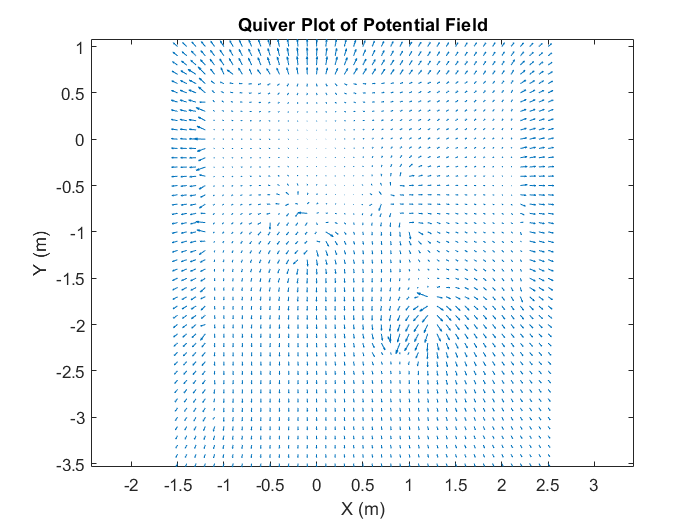

% Quiver Plot

syms x y
bob_radius = 0.25;

positions = load('all_positions.mat').all_positions;
headings  = load('all_headings.mat').all_headings;

all_points = [];

for i=1:2
    scan = load(['scan' num2str(i) '.mat']);
    
    p = positions(i, :);
    h = headings(i, :);
    
    orient = atan2(h(2), h(1));
    points = convertLidarToGlobal(scan.r, scan.theta, p, orient);
    
    all_points = [all_points ; points];
end

[line_inliers, circle_inliers, ~] = detectObjects(all_points, bob_radius);
p_field = create_potential_field(line_inliers, circle_inliers);
grad    = gradient(p_field, [x y]);

[xs, ys] = meshgrid(-1.5:0.1:2.5, -3.5:0.1:1);
v = double(subs(grad, {x, y}, {xs, ys}));
half = floor(length(v) / 2);

quiver(xs, ys, v(1:half, :), v(half+1:end, :))
axis equal
title('Quiver Plot of Potential Field')
xlabel('X (m)')
ylabel('Y (m)')

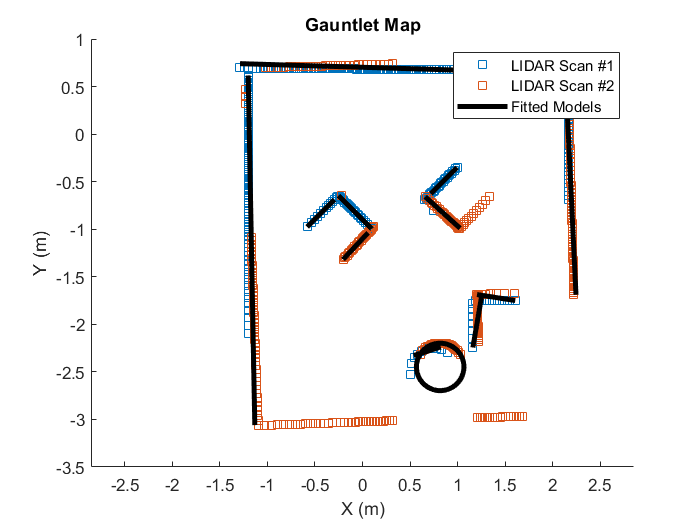

% Gauntlet map

syms x y
bob_radius = 0.25;

positions = load('all_positions.mat').all_positions;
headings  = load('all_headings.mat').all_headings;

all_points = [];

figure
hold on

for i=1:2
    scan = load(['scan' num2str(i) '.mat']);
    
    p = positions(i, :);
    h = headings(i, :);
    
    orient = atan2(h(2), h(1));
    points = convertLidarToGlobal(scan.r, scan.theta, p, orient);
    
    plot(points(:, 1), points(:, 2), 's')
    all_points = [all_points ; points];
end
[~, ~, circle_center, end_points] = detectObjects(all_points, bob_radius);

for i=1:size(end_points,1)
    plot([end_points(i,1) end_points(i,2)],[end_points(i,3) end_points(i,4)],'k','LineWidth',3)
end

circle_equation_explicit = (x-circle_center(1))^2 + (y-circle_center(2))^2 == bob_radius^2;
fimplicit(circle_equation_explicit,[-4*pi 4*pi],'k','LineWidth',3, 'DisplayName','Fitted BoB');

hold off
xlim([-1.5 2.5])
ylim([-3.5 1])
axis equal
legend({'LIDAR Scan #1', 'LIDAR Scan #2', 'Fitted Models'})
xlabel('X (m)')
ylabel('Y (m)')
title('Gauntlet Map')

% Gradient descent

syms x y
bob_radius = 0.25;

positions = load('all_positions.mat').all_positions;
headings  = load('all_headings.mat').all_headings;

v1 = positions(2, :);
v2 = positions(3, :);
positions(3, :) = v1 + ((v2 - v1) / (2*norm(v2 - v1)));

all_points = [];

for i=1:2
    scan = load(['scan' num2str(i) '.mat']);
    
    p = positions(i, :);
    h = headings(i, :);
    
    orient = atan2(h(2), h(1));
    points = convertLidarToGlobal(scan.r, scan.theta, p, orient);
    
    all_points = [all_points ; points];
end

[line_inliers, circle_inliers, ~] = detectObjects(all_points, bob_radius);
p_field = create_potential_field(line_inliers, circle_inliers);

figure
hold on

plot(positions(:, 1), positions(:, 2), 'r-')

[xs, ys] = meshgrid(-1.5:0.1:2.5, -3.5:0.1:1);
v = double(subs(p_field, {x, y}, {xs, ys}));
contour(xs, ys, v, 'k', 'ShowText', 'On')

axis equal
hold off
title('Contour Plot with Neato Path')
xlabel('X (m)')
ylabel('Y (m)')
legend('Neato Path')

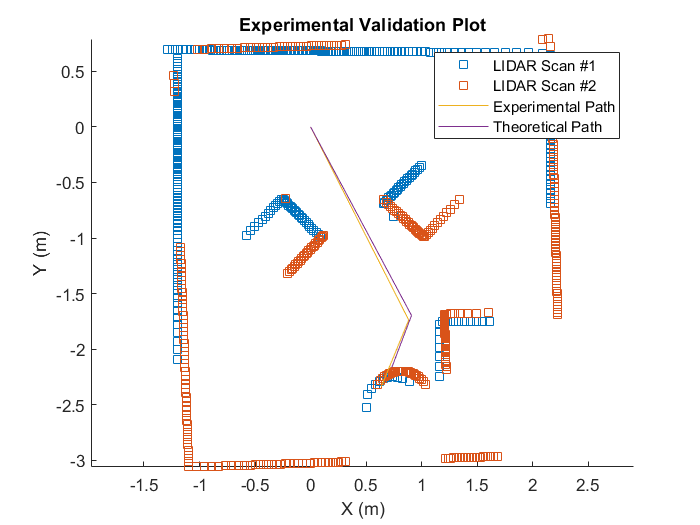

% Experimental validation

bob_radius = 0.25;

positions = load('all_positions.mat').all_positions;
headings  = load('all_headings.mat').all_headings;

v1 = positions(2, :);
v2 = positions(3, :);
positions(3, :) = v1 + ((v2 - v1) / (2*norm(v2 - v1)));

all_points = [];

figure
hold on

for i=1:2
    scan = load(['scan' num2str(i) '.mat']);
    
    p = positions(i, :);
    h = headings(i, :);
    
    orient = atan2(h(2), h(1));
    points = convertLidarToGlobal(scan.r, scan.theta, p, orient);
    
    plot(points(:, 1), points(:, 2), 's')
end

enc = readmatrix('encoder_data.csv');
enc = enc(1:455, :);
left  = diff(enc(:, 2)) ./ diff(enc(:, 1));
right = diff(enc(:, 3)) ./ diff(enc(:, 1));
l_vel = (left + right) / 2;
a_vel = (right - left) / 0.235;
t = diff(enc(:, 1));%cumsum(diff(enc(:, 1)));

thetas = cumsum(a_vel .* t);
x = cumsum(l_vel .* cos(thetas) .* t);
y = cumsum(l_vel .* sin(thetas) .* t);
plot(x, y)

plot(positions(:, 1), positions(:, 2))

axis equal
hold off
title('Experimental Validation Plot')
xlabel('X (m)')
ylabel('Y (m)')
legend({'LIDAR Scan #1', 'LIDAR Scan #2', 'Experimental Path', 'Theoretical Path'})